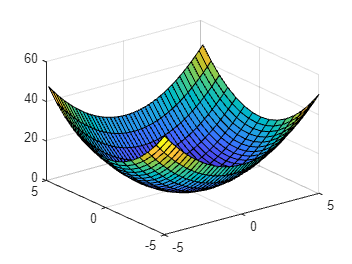

clear all, clc

% Curved surf
[X_curve, Y_curve] = meshgrid(-5:0.25:5, -5:0.7:5);
Z_curve = X_curve.^2 + Y_curve.^2;

% plane at angle
[X_plane, Z_plane] = meshgrid(-5:.75:5, 0:5:50);
skew_x = .5; % Skew factor
Y_plane = skew_x*X_plane ;



% Plot
figure;
surf(X_curve, Y_curve, Z_curve); hold on;

surf(X_plane, Y_plane, Z_plane);
xlabel('X'); ylabel('Y'); zlabel('Z');


plot_yn = 1
[x_intersect, y_intersect, z_intersect] = Mesh_Sheet_Intrsect(X_curve, Y_curve, Z_curve, X_plane, Y_plane, Z_plane, plot_yn);



function [x_intersect, y_intersect, z_intersect] = Mesh_Sheet_Intrsect(X_curve, Y_curve, Z_curve, X_plane, Y_plane, Z_plane, plot_yn)
    % Interpolate the curved mesh onto the grid points of the mesh plane
    Z_interpolated = interp2(X_curve, Y_curve, Z_curve, X_plane, Y_plane);

    % Extract the intersection points
    x_intersect = X_plane(1, :);
    y_intersect = Y_plane(1, :);
    z_intersect = Z_interpolated(1, :);



    if plot_yn
        % Plot the intersection
        figure;
        surf(X_curve, Y_curve, Z_curve); hold on;
        surf(X_plane, Y_plane, Z_plane);

        plot3(x_intersect, y_intersect, z_intersect, 'r-o', LineWidth=3);
        xlabel('X');    ylabel('Y');    zlabel('Z');    [az, el] = view;
        xlims = xlim;   ylims = ylim;   zlims = zlim;

        figure
        plot3(x_intersect, y_intersect, z_intersect, 'r-o', LineWidth=3);
        xlabel('X');    ylabel('Y');    zlabel('Z');    view(az, el);
        xlim(xlims);    ylim(ylims);    zlim(zlims);
    end
end
